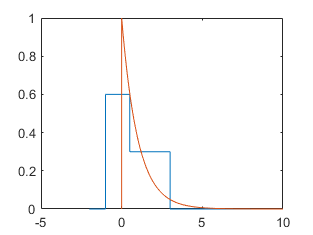

%Sinal de Entrada
tx0 = -2:0.01:-1;
tx1 = -1:0.01:0.5;
tx2 = 0.5:0.01:3;
tx3 = 3:0.01:10;
x0 = zeros(size(tx0));
x1 = 0.6*ones(size(tx1));
x2 = 0.3*ones(size(tx2));
x3 = zeros(size(tx3));
x = [x0 x1 x2 x3];
tx = [tx0 tx1 tx2 tx3];
figure 
plot(tx, x)
hold on

%Resposta Impulsiva 
th1 = 0:0.01:10;
h1 = exp(-th1);
h = [0 h1];
th = [0 th1];
plot(th, h)
hold off

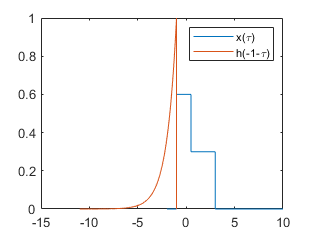


%Sem sobreposicao
t = -1;
figure
plot(tx, x, t - th, h)
legend("x(\tau)", "h(-1-\tau)")

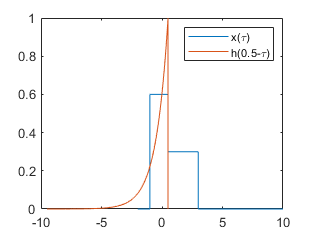


%Sobreposicao parcial
t = 0.5;
figure
plot(tx, x, t - th, h)
legend("x(\tau)", "h(0.5-\tau)")

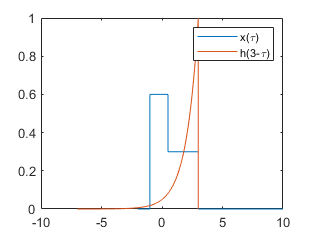


%Sobreposicao total
t = 3;
figure
plot(tx, x, t - th, h)
legend("x(\tau)", "h(3-\tau)")


%Determinando as integrais
syms t r
%Inicio da sobreposicao
f1 = 0.6*exp(-t+r); 
f2 = 0.3*exp(-t+r);
int1 = int(f1, r, -1, 0.5) 

$$int1 = \frac{3\,{\mathrm{e}}^{-t-1}\,\left({\mathrm{e}}^{3/2}-1\right)}{5}$$


%Sobreposicao completa
int2 = int1 + int(f2, r, 0.5, t)

$$int2 = \frac{3\,{\mathrm{e}}^{-t-1}\,\left({\mathrm{e}}^{3/2}-1\right)}{5}+\frac{3\,{\mathrm{e}}^{-t}\,\sqrt{\mathrm{e}}}{10}-\frac{3}{10}$$


%Sobreposicao estagio saida
int3 = int1 + int(f2, r, 0.5, 3)

$$int3 = \frac{3\,{\mathrm{e}}^{-t-1}\,\left({\mathrm{e}}^{3/2}-1\right)}{5}-\frac{3\,{\mathrm{e}}^{-t}\,\sqrt{\mathrm{e}}\,\left({\mathrm{e}}^{5/2}-1\right)}{10}$$

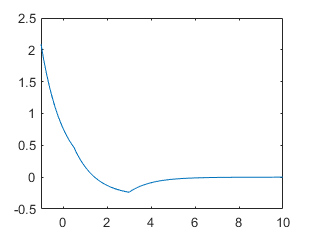


ts1 = -1:0.1:0.5;
ts2 = 0.5:0.1:3;
ts3 = 3:0.1:10;

y1 = subs(int1, ts1);
y2 = subs(int2, ts2);
y3 = subs(int3, ts3);

ys1 = [y1 y2 y3];
ts = [ts1 ts2 ts3];

plot(ts, ys1)

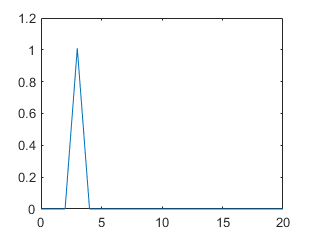

%Exercicio 2
t0 = 0:0.01:1-0.01;
t1 = 1:0.01:2;
t2 = 2+0.01:0.01:10;
t = [t0 t1 t2];

%Sinal entrada
x0 = zeros(size(t0));
x1 = ones(size(t1));
x2 = zeros(size(t2));
x = [x0 x1 x2];

%Resposta impulsiva
h0 = zeros(size(t0));
h1 = ones(size(t1));
h2 = zeros(size(t2));
h = [h0 h1 h2];

%Convolução 
ys2 = conv(x, h) * 0.01;
tys = 0:0.01:20;
plot(tys, ys2)